# Quorum Sensing Dynamics

This document explores the dynamics of population-level quorum sensing (QS) models. Data and parameters are from [Fekete 2010], including supplementary material available online at [https://academic.oup.com/femsec/article/72/1/22/556140#supplementary-data](https://academic.oup.com/femsec/article/72/1/22/556140#supplementary-data)

clear; clc; clf;  % clean workspace
rng default;      % set random number generator for reproducibility

## Model

The mathematical model is an ordinary differential equation for the signal concentration, *A,* as a function of the population density* N(t).*


$$\dot{A} =-\gamma A+\left(\alpha +\frac{\beta A^n }{{A_{\mathrm{thresh}} }^n +A^n }\right)\times N\left(t\right)$$


The model contains 5 parameters.

- *α* - constitutive production rate of AHL

- *β* - induced production rate of AHL

- *n* - degree of polymerization

- *Athresh* - threshold of AHL between low and increased activity

- *γ* - abiotic degradation rate of AHL

## Observations

Model parameters were estimated "from the first 10 h of the kinetic experiment with the baffled flasks" and from additional published data (e.g. abiotic degradation rate). Population density from the kinetic experiment is available in supplementary data as cell/mL. Convert those values to cell/L for consistent units.

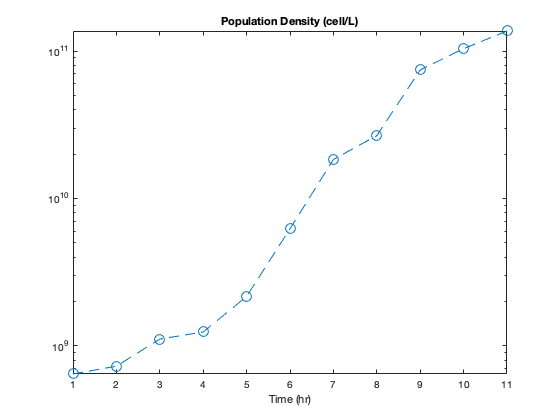

% Population density as a function of time
N = [
    6.43e5    % cell/mL at t = 0hr
    7.27e5    % cell/mL at t = 1hr
    1.11e6    % cell/mL at t = 2hr
    1.24e6    % cell/mL at t = 3hr
    2.16e6    % cell/mL at t = 4hr
    6.23e6    % cell/mL at t = 5hr
    1.84e7    % cell/mL at t = 6hr
    2.67e7    % cell/mL at t = 7hr
    7.46e7    % cell/mL at t = 8hr
    1.04e8    % cell/mL at t = 9hr
    1.37e8    % cell/mL at t = 10hr
] * 1e3;      % cell/mL => cell/L

semilogy(N, '--o', 'MarkerSize',10); 
title("Population Density (cell/L)");
xlabel("Time (hr)");

## Parameter Estimates

From Table 2. Note that the threshold concentration is reported as nmol/L. Convert that to mol/L for consistent units.

alpha = 2.3e-19;      % mol/cell/hr
beta = 2.3e-18;       % mol/cell/hr
n = 2.5;              % (no units)
Athresh = 70 / 1e9;   % nmol/L => mol/L
gamma = 0.005545;     % /hr

## Signal Dynamics

Equilibrium signal concentration as a function of population density can be calculated analytically if the degree of polymerization is approximated as 2 instead of 2.5, yielding a cubic equation.

Aeq = @(Nfixed) roots([
    -1 * gamma
    alpha * Nfixed + beta * Nfixed
    -1 * gamma * Athresh ^ 2
    alpha * Nfixed * Athresh ^ 2
]);

Show dynamics of signal concentration for various scenarios.

% Differential equation with fixed population density as additional parameter
dA_dt = @(t,A,Nfixed) -1 * gamma * A + (alpha + beta/((Athresh / A)^n + 1)) * Nfixed;

### Maximum Time to Equilibrium at Stationary Density

% Assume final population density is stationary density
Nstat = N(end);

% For maximum time, initial signal concentration is zero
A0 = 0;

[t,A] = ode23s(@(t,A) dA_dt(t,A,Nstat), [0 1000], A0);
plot(t,A);

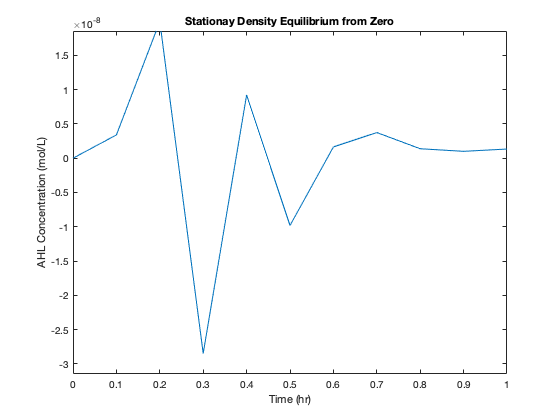

title("Stationay Density Equilibrium from Zero");
ylabel("AHL Concentration (mol/L)");
xlabel("Time (hr)");

## References

Agnes Fekete, Christina Kuttler, Michael Rothballer, Burkhard A. Hense, Doreen Fischer, Katharina Buddrus-Schiemann, Marianna Lucio, Johannes Müller, Philippe Schmitt-Kopplin, Anton Hartmann, Dynamic regulation of *N*-acyl-homoserine lactone production and degradation in *Pseudomonas putida*IsoF, *FEMS Microbiology Ecology*, Volume 72, Issue 1, April 2010, Pages 22–34, [https://doi.org/10.1111/j.1574-6941.2009.00828.x](https://doi.org/10.1111/j.1574-6941.2009.00828.x)